# Practica02MolinaRafael

Cambia el nombre del guión a Practica02tuapellidonombre

% Incluye aquí tu nombre y apellidos
% Tiempo: Incluye aquí el tiempo dedicado a realizar el guion

## Paso 1

A=[1:5];
p=[0.2 0.4 0.2 0.1 0.1];
D=huffmandict(A,p);
for i=1:length(A)
    fprintf('Letra Alfabeto %s Código %s\n',num2str(D{i,1}),num2str(D{i,2}))
end

## Paso 2

% A HACER POR LOS ESTUDIANTES.. INCLUIR CÓDIGO AQUÍ.

% Podemos utilizar otros símbolos para los elementos del alfabeto. Halla y
% muestra, siguiendo el esquema del paso anterior, el código de Huffman
% correspondiente al alfabeto {P,Q,R,S,T} con probabilidades
% p=[0.2  0.4  0.2  0.1  0.1]. Cuya ejecución debe producir la salida que se
% muestra más abajo. Incluye el código en el paso 2 de Practica02ApellidoNombre.m
clear variables; close all;
A=['P' 'Q' 'R' 'S' 'T'];
p=[0.2 0.4 0.2 0.1 0.1];
D=huffmandict(uint8(A),p);
for i=1:length(A)
    fprintf('Letra Alfabeto %s Código %s\n',A(i),num2str(D{i,2}))
end

## Paso 3

A=[1:5];
p=[0.2 0.4 0.2 0.1 0.1];
D=huffmandict(A,p,2,'min');

for i=1:length(A)
    fprintf('Letra Alfabeto %s Código %s\n',num2str(D{i,1}),num2str(D{i,2}))
end

## Paso 4

A=[1:5];
p=[0.2 0.4 0.2 0.1 0.1];
rng(0);
stream= randsrc(1,10,[A;p])

## Paso 5

clc; clear all;
fichero= 'Don Quijote de la Mancha - Miguel de Cervantes.txt'
fid=fopen(fichero,'r')
seq=fread(fid,'*uint8');
fclose(fid);
seq=reshape(seq,1,length(seq)); %leidos datos en seq vector fila
fprintf('Tamaño del fichero original en bytes  %d\n',numel(seq))

## Paso 6

letras=[0:255];
histo=histc(seq,letras); %calculamos histograma e indices
bar(letras,histo);
axis('tight');
xlabel('letras [0:255]');
ylabel('Frecuencias');
title('Histograma');
xlabel('letras [0:255]');
ylabel('Frecuencias');
title('Histograma');

## Paso 7

% A HACER POR LOS ESTUDIANTES. INCLUIR CÓDIGO DE MATLAB AQUÍ

% De las 256 letras del alfabeto solo usamos las que aparecen en el
% fichero 'Don Quijote de la Mancha - Miguel de Cervantes.txt'. Hállalas y
% calcula sus probabilidades. Puedes utilizar la función find, por ejemplo
% find(histo>0) que devuelve las posiciones de la matriz histo que almacenan
% valores mayores que cero. No debes confundir las posiciones de las letras
% en letras que van de 1 a 256 con los valores de las letras que van de
% 0 a 255. Escribe el código correspondiente en el paso 7 de
% Practica02ApellidoNombre.m

i=find(histo>0)
letras_usadas = i-1
prob_letras_usadas =  histo(i) ./ sum(histo)

## Paso 8

[dict,avglen] = huffmandict(letras_usadas,prob_letras_usadas) ; %construimos el diccionario
seq_codificada = huffmanenco(seq,dict); %codificamos la señal
fprintf('Número de letras usadas %d\n',numel(letras_usadas))
fprintf('Longitud la secuencia codificada %d\n', length(seq_codificada))

## Paso 9

tamagno_comprimido=(length(letras_usadas)+1)*1+ ...
    (length(letras_usadas)+1)*8+ ...
    ceil(length(seq_codificada)/8);
fprintf('Tamaño fichero comprimido en bytes  %d\n',tamagno_comprimido)

## Paso 10

deco=huffmandeco(seq_codificada,dict);

## Paso 11

fprintf('¿Coinciden original y comprimido 1(S) 0 (N)?, %d\n',...
    isequal(seq,uint8(deco)))

## Paso 12

% A HACER POR LOS ESTUDIANTES. ENTREGA DISCUSION EN PDF.

% Incluye en el paso 12 del  fichero Practica02ApellidoNombre.pdf el
% tamaño del fichero original y el comprimido. Incluye también el factor de
% compresión.

## Paso 13

clc; clear all;
N=9;
Fichero=cell(N);
Fichero{1}='constitucion española.txt';
Fichero{2}='Fundacion e Imperio - Isaac Asimov.txt';
Fichero{3}='Cinco semanas en globo - Julio Verne.txt';
Fichero{4}='ptt1.pbm';
Fichero{5}='ptt4.pbm';
Fichero{6}='ptt8.pbm';
Fichero{7}='camera.pgm';
Fichero{8}='bird.pgm';
Fichero{9}='bridge.pgm';

## Paso 14

% A HACER POR LOS ESTUDIANTES. ENTREGA DISCUSION EN PDF E INCLUYE EL CÓDIGO
% MATLAB AQUÍ

% Para cada uno de los ficheros anteriores: ‘constitucion española.txt’,
% ‘Fundacion e Imperio - Isaac Asimov.txt’, ‘Cinco semanas en globo - Julio Verne.txt’,
% ptt1.pbm, ptt4.pbm, ptt8.pbm, camera.pgm, bird.pgm y  bridge.pgm escribe
% en el paso 14 de Practica02ApellidoNombre.m el código Matlab que calcule
%el tamaño del fichero original, el comprimido usando el código de Huffman
% y el factor de compresión obtenido en cada uno de los casos. El código
%Matlab debe comprobar también que los ficheros originales y descomprimidos
%son iguales.

% Completa en el paso 14 de Practicaq02ApellidoNombre.pdf la tabla siguiente, realiza una
% comparación crítica de los resultados obtenidos y explica la variación en
% el factor de compresión.

for i = 1:N
    %1.LECTURA DE LOS FICHEROS Y DE LA SECUENCIA
    fid=fopen(Fichero{i},'r')
    seq_original=fread(fid,'*uint8');
    fclose(fid);
    seq_original=reshape(seq_original,1,length(seq_original)); %leidos datos en seq vector fila
    fprintf('Tamaño original del fichero %s en bytes  %d\n',Fichero{i} ,numel(seq_original))
   
    %Guarda la seceuncia oriGinal
    Fichero{i, 2} = seq_original
    Fichero{i, 3} = numel(seq_original)
    
    %2.CALCULAR HISTOGRAMA Y PROBABILIDADES 
    lectura=[0:255];
    histo=histc(seq_original,lectura); %calculamos histograma e indices
    %Calcualr probabilidades de las letras usadas
    index=find(histo>0)
    letras_usadas = index-1
    prob_letras_usadas =  histo(index) ./ sum(histo)
    
    %3.CONSTRUCCION DEL DICCIONARIO Y CIDIFICADO DE LA SEÑAL
    [dict,avglen] = huffmandict(letras_usadas,prob_letras_usadas) ; %construimos el diccionario
    seq_codificada = huffmanenco(seq_original,dict); %codificamos la señal
    fprintf('Número de letras usadas %d\n',numel(letras_usadas))
    fprintf('Longitud la secuencia codificada %d\n', length(seq_codificada));
    
    Fichero{i, 4} = seq_codificada
    Fichero{i, 5} = dict
    %4.CALCULAR TAMAÑO COMPRIMIDO
    tamagno_comprimido=(length(letras_usadas)+1)*1+ ...
                       (length(letras_usadas)+1)*8+ ...
                       ceil(length(seq_codificada)/8);
    fprintf('Tamaño fichero comprimido en bytes  %d\n',tamagno_comprimido)
    
    Fichero{i, 6} = tamagno_comprimido
    
    %5.DECODIFICADO SEÑAL
    deco=huffmandeco(seq_codificada,dict);
    
    %6.COMPORBACION SEÑAL ORIGINAL Y DECODIFICADA
    fprintf('¿Coinciden original y comprimido 1(S) 0 (N)?, %d\n', isequal(seq_original,uint8(deco)))
    
end

%COMPROBACION Y RESULTADOS
%MOSTRAR RESULTADOS DE FORMA ORDENADA
fprintf("Resultados:")
for i = 1:N
   FC = Fichero{i, 3}/Fichero{i,6}
   
   %5.DECODIFICADO SEÑAL
   deco=huffmandeco(Fichero{i,4},Fichero{i,5}); % seg_codificada y diccionario
   
   fprintf("//////////////////////////")
   fprintf("Fichero %s",Fichero{i})
   fprintf("Tamaño original: %d\n" + ...
           "Tamaño comprimido: %d\n" + ...
           "FC: %f\n" + ...
           "Comprobacion de secuenciuas:\n", Fichero{i, 3},Fichero{i,6}, FC)
   
    %6.COMPORBACION SEÑAL ORIGINAL Y DECODIFICADA
    fprintf('¿Coinciden original y comprimido 1(S) 0 (N)?, %d\n', isequal(Fichero{i, 2},uint8(deco)))
end


## Paso 15

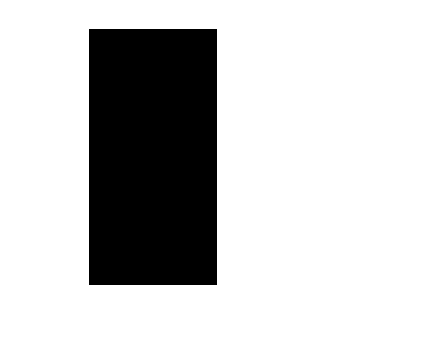

clc; close all; clear all;
M=256;
img=uint8(zeros(M));
img(:,129:M)=255;
imshow(img);

img16=uint16(img);
img2=255*img16(:,1:2:size(img,2))+img16(:,2:2:size(img,2));
[U,V]=size(img2);
seq=reshape(img2,1,U*V);

## Paso 16

% A HACER POR LOS ESTUDIANTES. INCLUYE CÓDIGO MATLAB AQUÍ

% Codifica la matriz img, que no agrupa los bytes de dos en dos, usando el
% código de Huffman, comprueba que coinciden la secuencia original y la
% decodificación de la comprimida, calcula el espacio que ocupa la imagen
% comprimida incluida la cabecera y el factor de compresión. Escribe el
% trozo de código en el paso 16 de Practica02ApellidoNombre.m.

% Escribe en el paso 16 de Practica02ApellidoNombre.pdf el factor de
% compresión calculada.

[U1,V1] = size(img)

U1 = 256

V1 = 256

seq1 = reshape(img,1,U1*V1)

seq1 = 1×65536 uint8 row vector
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0



TamImg = numel(seq1)

TamImg = 65536

histo=histc(seq1,[0:255]);

index=find(histo>0)

index =      1   256


letras_usadas = index-1

letras_usadas =      0   255


prob_letras_usadas =  histo(index) ./ sum(histo)

prob_letras_usadas =     0.5000    0.5000



[dict,avglen] = huffmandict(letras_usadas,prob_letras_usadas) ; %construimos el diccionario
seq_codificada = huffmanenco(seq1,dict);

tamagno_comprimido=(length(letras_usadas)+1)*1+ ...
                   (length(letras_usadas)+1)*8+ ...
                   ceil(length(seq_codificada)/8);

deco=huffmandeco(seq_codificada,dict);

FC = TamImg/tamagno_comprimido

FC = 7.9737


fprintf('Número de letras usadas: %d\n',numel(letras_usadas))

Número de letras usadas: 2


fprintf('Longitud la secuencia codificada: %d\n', length(seq_codificada));

Longitud la secuencia codificada: 65536


fprintf('Tamaño fichero sin comprimir      : %d', TamImg);

Tamaño fichero sin comprimir      : 65536

fprintf('Tamaño fichero comprimido en bytes: %d\n',tamagno_comprimido)

Tamaño fichero comprimido en bytes: 8219


fprintf('FC: %f', FC)

FC: 7.973719

fprintf('¿Coinciden original y comprimido 1(S) 0 (N)?, %d\n', isequal(seq1,uint8(deco)))

¿Coinciden original y comprimido 1(S) 0 (N)?, 1


## Paso 17

% Codifica la matriz img2, que agrupa los bytes de dos en dos, usando el
% código de Huffman, comprueba que coinciden la secuencia original y la
% decodificación de la comprimida, calcula el espacio que ocupa la imagen
% comprimida incluida la cabecera y el factor de compresión. Escribe el
% trozo de código en el paso 17 de Practica02ApellidoNombre.m.

% Escribe en el paso 17 de Practica02ApellidoNombre.pdf el factor de compresión
% calculada.

TamImg = numel(seq)*2

TamImg = 65536

histo=histc(seq,[0:(256*256)-1]);

index=find(histo>0)

index =            1       65281


letras_usadas = index-1

letras_usadas =            0       65280


prob_letras_usadas =  histo(index) ./ sum(histo)

prob_letras_usadas =     0.5000    0.5000



[dict,avglen] = huffmandict(letras_usadas,prob_letras_usadas) ; %construimos el diccionario
seq_codificada = huffmanenco(seq,dict);

tamagno_comprimido=(length(letras_usadas)+1)*2+ ...
                   (length(letras_usadas)+1)*8+ ...
                   ceil(length(seq_codificada)/8);%Lo queremos en bytes

deco=huffmandeco(seq_codificada,dict);

FC = TamImg/tamagno_comprimido

FC = 15.8837


fprintf('Número de letras usadas: %d\n',numel(letras_usadas))

Número de letras usadas: 2


fprintf('Longitud la secuencia codificada: %d\n', length(seq_codificada));

Longitud la secuencia codificada: 32768


fprintf('Tamaño fichero sin comprimir      : %d', TamImg);

Tamaño fichero sin comprimir      : 65536

fprintf('Tamaño fichero comprimido en bytes: %d\n',tamagno_comprimido)

Tamaño fichero comprimido en bytes: 4126


fprintf('FC: %f', FC)

FC: 15.883665

fprintf('¿Coinciden original y comprimido 1(S) 0 (N)?, %d\n', isequal(seq,uint16(deco)))

¿Coinciden original y comprimido 1(S) 0 (N)?, 1


## Paso 18

% A HACER POR LOS ESTUDIANTES. Entrega discusión en pdf

% ¿Cuáles son los factores de compresión para las matrices img2 e img
% obtenidas en los dos pasos anteriores?. Discute los resultados obtenidos
% en los dos pasos anteriores en el paso 18 de Practica02ApellidoNombre.pdf.

## Paso 19

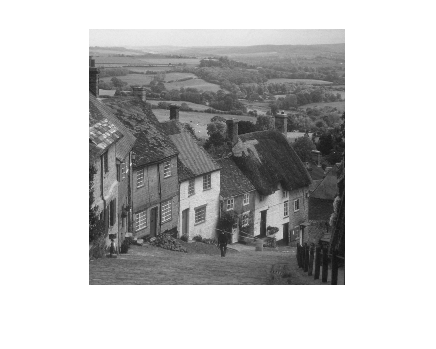

close all; clear all;
img=imread('goldhill.pgm');
imshow(img);

img16=uint16(img);
img2=255*img16(:,1:2:size(img,2))+img16(:,2:2:size(img,2));

## Paso 20

% A HACER POR LOS ESTUDIANTES. Entrega discusión en pdf y código Matlab
% aquí.

% Incluye en el paso 20 del fichero Practica02ApellidoNombre.m el código
% en Matlab que calcula los factores de compresión para estas nuevas
% matrices img2 e img obtenidas a partir de la imagen goldhill.pgm del paso
% anterior. Incluye el tamaño de la cabecera. Si no pudieses codificar alguna
% de las dos matrices explica por qué.

% Discute los resultados obtenidos en el paso 20 de Practica02ApellidoNombre.pdf.




## Paso 21

clc, close all; clear all;
file_name = 'miss_am.yuv';
file_format = 'QCIF_PAL';
num_of_frames = 30;
[yuv_movie, yuv_array] = readYUV(file_name, num_of_frames, ...
    file_format);
implay(yuv_movie)
fotograma1=yuv_array(:,:,1,1);
fotograma2=yuv_array(:,:,1,2);
figure; imshow(fotograma1);
figure; imshow(fotograma2);

## Paso 22

% A HACER POR LOS ESTUDIANTES. INCLUIR CÓDIGO AQUÍ Y DISCUSIÓN EN EL
% FICHERO PDF

% Utiliza el código de Huffman para codificar la matriz fotograma2. Escribe
% en el paso 22 de Practica02ApellidoNombre.m el código en Matlab para
% calcular el histograma de la imagen original, el tamaño de la matriz
% comprimida, incluida la cabecera, y su factor de  compresión. Comprueba
% que la matriz original y la decodificación de la comprimida coinciden.

% Incluye el histograma, el tamaño de la matriz original y el de la
% comprimida (con cabecera) en el paso 22 de Practica02ApellidoNombre.pdf.
% Escribe también el factor de compresión

## Paso 23

% A HACER POR LOS ESTUDIANTES. INCLUIR CÓDIGO MATLAB AQUÍ

% Como puedes comprobar la nueva representación de la imagen ocupa menos
% espacio que la imagen original pero la reducción del tamaño no es grande.
% Escribe código en Matlab que dibuje el histograma de fotograma2-fotograma1,
% codifique la matriz diferencia usando Huffman, compruebe que fotograma2
% coincide con su reconstrucción y calcule el tamaño de
% fotograma2-fotograma1 comprimido, incluida su cabecera. Incluye el código
% en el paso 23  de Practica02ApellidoNombre.m. Este ejercicio puedes
% hacerlo de dos formas según codifiques las diferencias. Realízalo como
% consideres más apropiado.

% Incluye el histograma de fotograma2-fotograma1, y el tamaño de la
% matriz comprimida (con cabecera) en el paso 23 de Practica02ApellidoNombre.pdf.
% Escribe también el factor de compresión.

## Paso 24

% A HACER POR LOS ESTUDIANTES. Entrega discusión en pdf

% Compara en el paso 24 del fichero Practica02ApellidoNombre.pdf los
% resultados obtenidos en los pasos 22 y 23. ¿A qué se debe la mejora?

## Paso 25

% A HACER POR LOS ESTUDIANTES. Entrega discusión en pdf

% En el paso 9 nos dejamos pendiente detectar que habíamos decodificado
% toda la secuencia de 0s y 1s. Discute en el paso 25 de
% Practica02ApellidoNombre.pdf posibles soluciones a este problema.

## Paso 26

% A HACER POR LOS ESTUDIANTES. Entrega discusión en pdf

% En el paso 9 definimos una cabecera. Se te ocurre alguna(s) mejora(s) que
% ahorre(n) espacio?. Incluye tu respuesta en el paso 26 de
% Practica02ApellidoNombre.pdf.